clear
%%%%%%%%% Setup %%%%%%%%%%
r_lox_wet = 1.04;
r_lox_dry = 0.74;

r_fuel_wet = 0.52;
r_fuel_dry = 0.30;

r_eng = 0.2;
r_body = 0.83;
r_load = 1.46;

m_prop_max = 20;
m_load = 5;
m_eng = 14;
m_body = 10;
%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% Mass calc %%%%%%%%
m_dry = [m_eng + m_body; m_load + m_eng + m_body]

m_dry =     24
    29


m_wet = 2*m_prop_max + m_dry

m_wet =     64
    69


m_burn = 0:0.5:(m_prop_max)

m_burn =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000



m = m_wet-2*m_burn

m =     64    63    62    61    60    59    58    57    56    55    54    53    52    51    50    49    48    47    46    45    44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    29    28    27    26    25    24
    69    68    67    66    65    64    63    62    61    60    59    58    57    56    55    54    53    52    51    50    49    48    47    46    45    44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    29


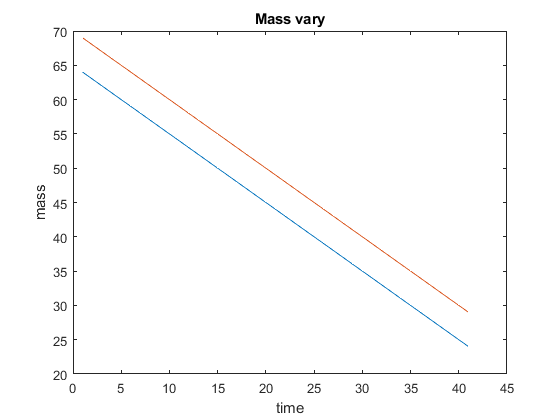

plot(m')
hold off
title("Mass vary")
xlabel("time")
ylabel("mass")


m_prop = m_prop_max-m_burn

m_prop =    20.0000   19.5000   19.0000   18.5000   18.0000   17.5000   17.0000   16.5000   16.0000   15.5000   15.0000   14.5000   14.0000   13.5000   13.0000   12.5000   12.0000   11.5000   11.0000   10.5000   10.0000    9.5000    9.0000    8.5000    8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000    4.5000    4.0000    3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%% CM calc %%%%%%%%
r_dry = [(m_body*r_body + m_eng*r_eng)./m_dry(1);
         (m_load*r_load + m_body*r_body + m_eng*r_eng)./m_dry(2)]

r_dry =     0.4625
    0.6345


r_lox = m_prop/m_prop_max*(r_lox_wet - r_lox_dry) + r_lox_dry

r_lox =     1.0400    1.0325    1.0250    1.0175    1.0100    1.0025    0.9950    0.9875    0.9800    0.9725    0.9650    0.9575    0.9500    0.9425    0.9350    0.9275    0.9200    0.9125    0.9050    0.8975    0.8900    0.8825    0.8750    0.8675    0.8600    0.8525    0.8450    0.8375    0.8300    0.8225    0.8150    0.8075    0.8000    0.7925    0.7850    0.7775    0.7700    0.7625    0.7550    0.7475    0.7400


r_fuel = m_prop/m_prop_max*(r_fuel_wet - r_fuel_dry) + r_fuel_dry

r_fuel =     0.5200    0.5145    0.5090    0.5035    0.4980    0.4925    0.4870    0.4815    0.4760    0.4705    0.4650    0.4595    0.4540    0.4485    0.4430    0.4375    0.4320    0.4265    0.4210    0.4155    0.4100    0.4045    0.3990    0.3935    0.3880    0.3825    0.3770    0.3715    0.3660    0.3605    0.3550    0.3495    0.3440    0.3385    0.3330    0.3275    0.3220    0.3165    0.3110    0.3055    0.3000


r_wet = [(m_prop_max*r_lox_wet + m_dry.*r_dry + m_prop_max*r_fuel_wet)./m_wet]

r_wet =     0.6609
    0.7188


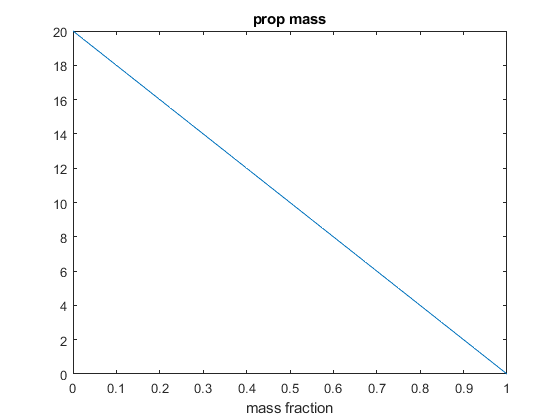


plot(m_burn/(m_prop_max),m_prop)
title("prop mass")
xlabel("mass fraction")

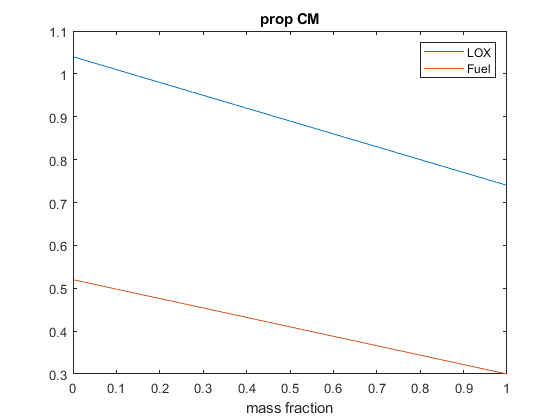


plot(m_burn/m_prop_max,r_lox)
hold on
plot(m_burn/m_prop_max,r_fuel)
hold off
title("prop CM")
xlabel("mass fraction")
legend("LOX", "Fuel")

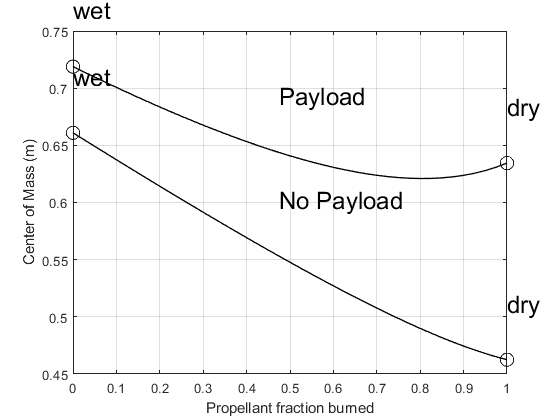


r = [((m_prop).*(r_lox + r_fuel) + m_dry.*r_dry)./m];
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%% CM Plot %%%%%%%%%%%%%
plot(m_burn(1)/m_prop_max,r(:,1),"blacko", "MarkerSize", 10);
hold on
plot(m_burn(end)/m_prop_max,r(:,end),"blacko", "MarkerSize", 10);
plot(m_burn/m_prop_max,r,'Color','black','LineWidth',1);
hold off

text(m_burn(1)/m_prop_max,r(1,1)+0.05,"wet",'FontSize',18)
text(m_burn(end)/m_prop_max,r(1,end)+0.05,"dry",'FontSize',18)
text(m_burn(1)/m_prop_max,r(2,1)+0.05,"wet",'FontSize',18)
text(m_burn(end)/m_prop_max,r(2,end)+0.05,"dry",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max,r(1,floor(end/2))+0.05,"No Payload",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max,r(2,floor(end/2))+0.05,"Payload",'FontSize',18)
grid on
xlabel("Propellant fraction burned")
ylabel("Center of Mass (m)")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% Rot Inertia %%%%%%%%%%%
% lengths
l_load = 0.1;
l_body = 1.64;
l_eng = 0.3;
l_lox = (r_lox-r_lox_dry)*2;
l_fuel = (r_fuel-r_fuel_dry)*2;

% x axis
I_x_load = 0.5*m_load*0.15^2;
I_x_body = 0.5*m_body*0.15^2;
I_x_eng = 0.5*m_eng*0.1^2;
I_x_fuel = 0.5*m_prop.*0.15.^2;
I_x_lox = 0.5*m_prop.*0.15.^2;

I_x_dry = [I_x_body + I_x_eng;
           I_x_load + I_x_body + I_x_eng]

I_x_dry =     0.1825
    0.2387


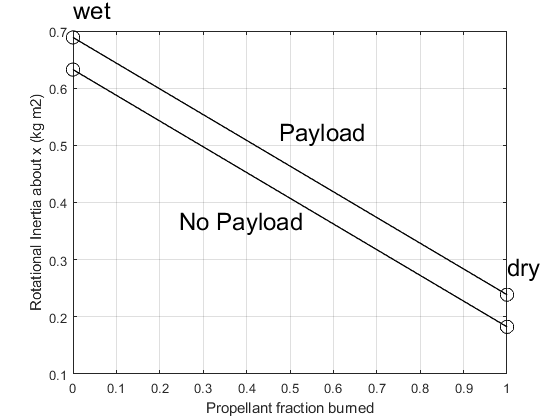

I_x = I_x_dry + I_x_lox + I_x_fuel;

plot(m_burn/m_prop_max, I_x,'Color','black','LineWidth',1);
hold on
plot(m_burn(1)/m_prop_max,I_x(:,1),"blacko", "MarkerSize", 10);
plot(m_burn(end)/m_prop_max,I_x(:,end),"blacko", "MarkerSize", 10);
hold off
text(m_burn(1)/m_prop_max,I_x(2,1)+0.05,"wet",'FontSize',18)
text(m_burn(end)/m_prop_max,I_x(2,end)+0.05,"dry",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max-0.23,I_x(1,floor(end/2))-0.05,"No Payload",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max,I_x(2,floor(end/2))+0.05,"Payload",'FontSize',18)
grid on
xlabel("Propellant fraction burned")
ylabel("Rotational Inertia about x (kg m2)")

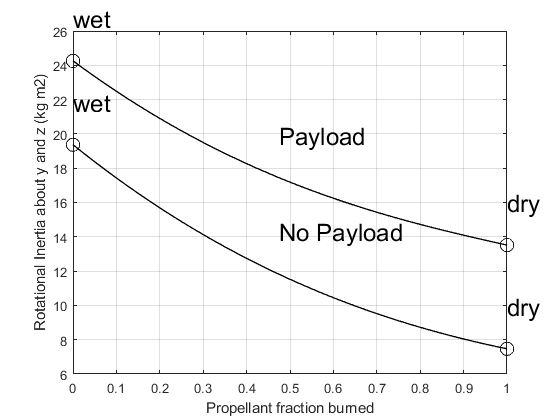


% yz axis
I_yz_load = m_load*(0.25*r_load^2 + 1/12*l_load^2);
I_yz_body = m_body*(0.25*r_body^2 + 1/12*l_body^2);
I_yz_eng = m_eng*(0.25*r_eng^2 + 1/12*l_eng^2);
I_yz_lox = m_prop.*(0.25*r_lox.^2 + 1/12*l_lox.^2);
I_yz_fuel = m_prop.*(0.25*r_fuel.^2 + 1/12*l_fuel.^2);

I_yz_dry = [I_yz_body + m_body*(r_body-r(1)).^2 + I_yz_eng + m_eng*(r_eng-r(1)).^2;
            I_yz_load + m_load*(r_load-r(2)).^2 + I_yz_body + m_body*(r_body-r(2)).^2 + I_yz_eng + m_eng*(r_eng-r(2)).^2];
I_yz = I_yz_dry + m_dry.*(r_dry-r).^2 + I_yz_fuel + m_prop.*(r_fuel-r).^2 + I_yz_lox + m_prop.*(r_lox-r).^2;

plot(m_burn/m_prop_max, I_yz,'Color','black','LineWidth',1);
hold on
plot(m_burn(1)/m_prop_max,I_yz(:,1),"blacko", "MarkerSize", 10);
plot(m_burn(end)/m_prop_max,I_yz(:,end),"blacko", "MarkerSize", 10);
hold off
text(m_burn(1)/m_prop_max,I_yz(1,1)+2.5,"wet",'FontSize',18)
text(m_burn(1)/m_prop_max,I_yz(2,1)+2.5,"wet",'FontSize',18)
text(m_burn(end)/m_prop_max,I_yz(1,end)+2.5,"dry",'FontSize',18)
text(m_burn(end)/m_prop_max,I_yz(2,end)+2.5,"dry",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max,I_yz(1,floor(end/2))+2.5,"No Payload",'FontSize',18)
text(m_burn(floor(end/2))/m_prop_max,I_yz(2,floor(end/2))+2.5,"Payload",'FontSize',18)
grid on
xlabel("Propellant fraction burned")
ylabel("Rotational Inertia about y and z (kg m2)")